clear all; close
L1=4; L2=3; L3=2;
P1=[0 0 0]'; PC1=[L1/2 0 0]';
P2=[L1 0 0]';PC2=[L2/2 0 0]';
P3=[L2 0 0]';PC3=[L3/2 0 0]';
m1=20; m2=15; m3=10;
I1=[0 0 0;
    0 0 0;
    0 0 0.5];
I2=[0 0 0;
    0 0 0;
    0 0 0.2];
I3=[0 0 0;
    0 0 0;
    0 0 0.1];
link1=Link('d',0,'a',L1,'alpha',0,'m',m1,'r',-PC1,'I',I1); % here I use standard DH, thus -PC1
link2=Link('d',0,'a',L2,'alpha',0,'m',m2,'r',-PC2,'I',I2);
link3=Link('d',0,'a',L3,'alpha',0,'m',m3,'r',-PC3,'I',I3); 
manipulator=link1+link2+link3;
[T,Theta,Theta_dot]=manipulator.fdyn(4,@Torque,[-pi/3 pi/2 pi/6],[0 0 0])

T =          0
    0.0002
    0.0005
    0.0007
    0.0009
    0.0021
    0.0032
    0.0044
    0.0056
    0.0114


Theta =    -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236
   -1.0472    1.5708    0.5236


Theta_dot =          0         0         0
    0.0000   -0.0000    0.0001
    0.0000   -0.0000    0.0001
    0.0000   -0.0000    0.0002
    0.0000   -0.0000    0.0002
    0.0001   -0.0001    0.0005
    0.0001   -0.0002    0.0007
    0.0002   -0.0002    0.0010
    0.0002   -0.0003    0.0012
    0.0005   -0.0006    0.0025


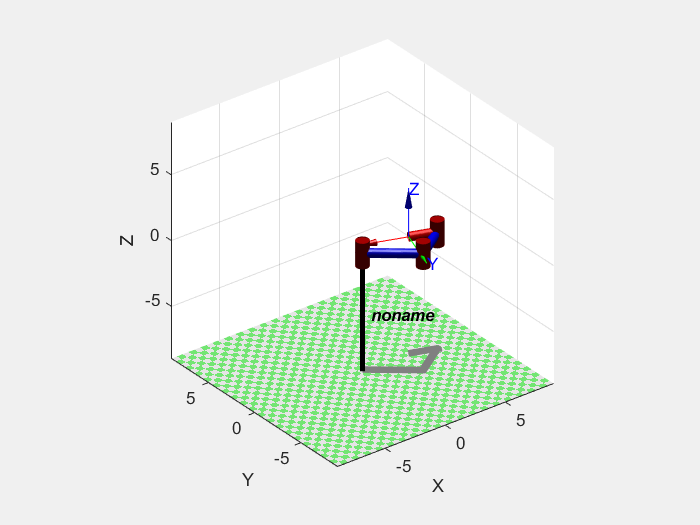

manipulator.plot(Theta,'delay',4/56) % put this animation before the plots below to avoid trouble

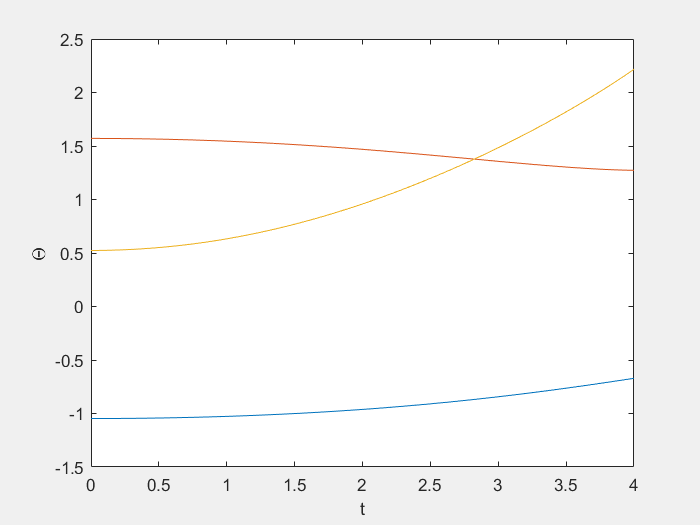

plot(T,Theta)
xlabel('t');ylabel('\Theta');

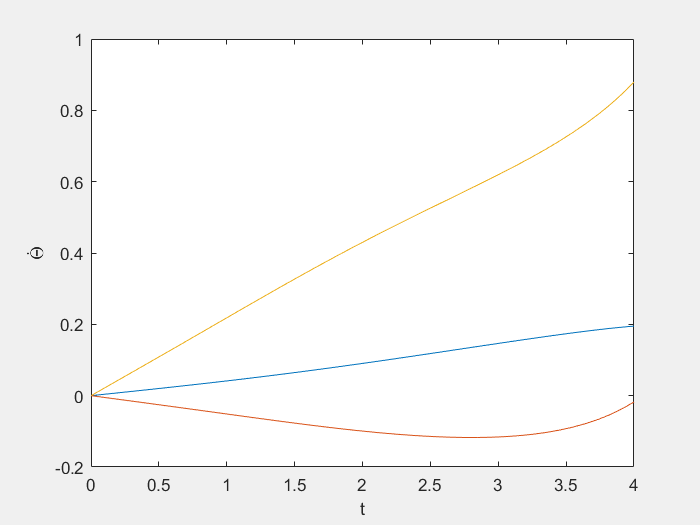

plot(T,Theta_dot)
xlabel('t');ylabel('$\dot{\Theta}$', 'Interpreter','latex');

function tau=Torque(ROBOT,T,Q,QD)
    tau=[20 5 1];
end